# `Exp-03: Symbolic,Function,Derivatives and Variables`

##  `Table of Contents:`

- Symboloic variable and Symbolic expression

- Exercise

- Differentiation

- Exercise

#### Symboloic variable and Symbolic expression

syms x
y=sin(x)

$$y = \sin\left(x\right)$$

syms a b c x
f=a*x^2+b*x+c

$$f = a\,x^{2}+b\,x+c$$

%Create an expression
syms t
g=exp(t)+sin(t)+sin(t^2)+2*cos(3*t)

$$g = 2\,\cos\left(3\,t\right)+\sin\left(t^{2}\right)+{\mathrm{e}}^{t}+\sin\left(t\right)$$

f=exp(t+1)

$$f = {\mathrm{e}}^{t+1}$$

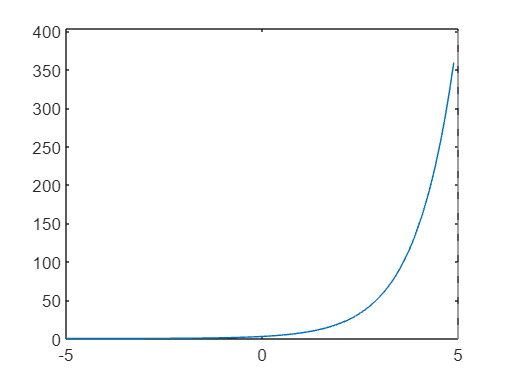

fplot(f)

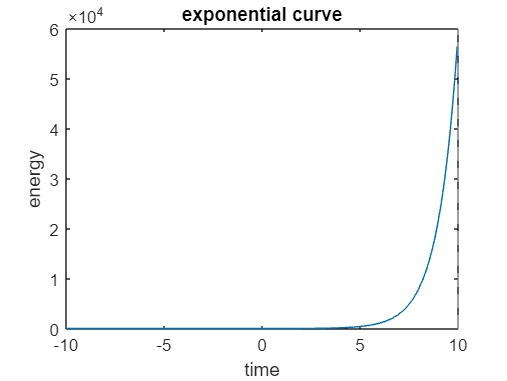

fplot(f,[-10,10])
title('exponential curve')
xlabel('time')
ylabel('energy')

#### Exercise

%Create the expression x^2+5x+6 and store it in expr
syms x
expr=x^2+5*x+6

$$expr = x^{2}+5\,x+6$$

%Create a symbolic variable a,b,c.Then create an expression for a second order polynomial ax^2+b*x+c
syms a b c x
y=a*x^2+b*x+c

$$y = a\,x^{2}+b\,x+c$$

%Creat an expression 3x/2+4 and store in 'ylinear'.Use fplot to visualize ylinear.
ylinear=(3*x)/2+4

$$ylinear = \frac{3\,x}{2}+4$$

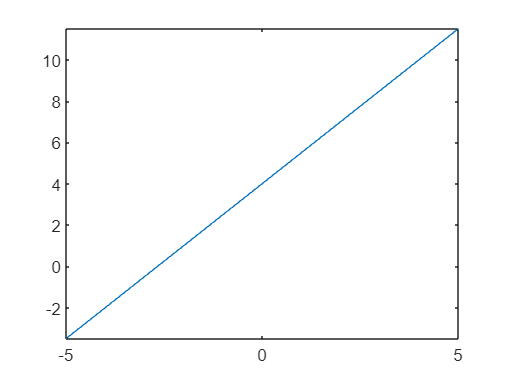

fplot(ylinear)

%Create the expression x^3/2-2*x+3 and stole it is ycubic.Use fplot to visualize ycubic and add a plot of ylinear to our plot of y-cubic use fplot to visualize ycubic.Also plot ycubic form -1 to 3
ycubic=x^3/2-2*x+3

$$ycubic = \frac{x^{3}}{2}-2\,x+3$$

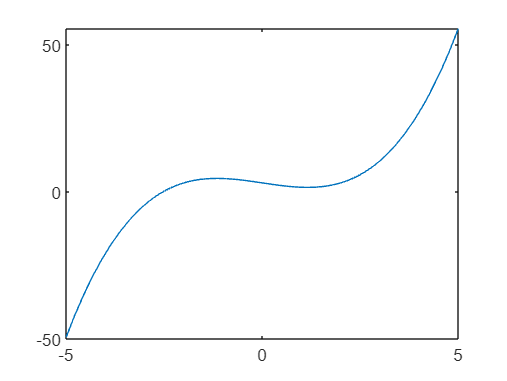

fplot(ycubic)

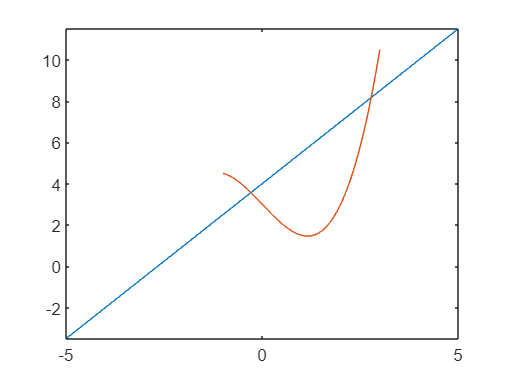

fplot(ylinear)
hold on
fplot(ycubic,[-1,3])
hold off

#### Differentiation

%Creating expression
syms x
g=exp(x)*cos(2*x)

$$g = \cos\left(2\,x\right)\,{\mathrm{e}}^{x}$$

g_1=diff(g,x) %1st order derivative

$$g\_1 = \cos\left(2\,x\right)\,{\mathrm{e}}^{x}-2\,\sin\left(2\,x\right)\,{\mathrm{e}}^{x}$$

g_2=diff(g,x,2) %2nd order derivative

$$g\_2 = -3\,\cos\left(2\,x\right)\,{\mathrm{e}}^{x}-4\,\sin\left(2\,x\right)\,{\mathrm{e}}^{x}$$

%or
g_2=diff(g_1)

$$g\_2 = -3\,\cos\left(2\,x\right)\,{\mathrm{e}}^{x}-4\,\sin\left(2\,x\right)\,{\mathrm{e}}^{x}$$

g_10=diff(g,x,10)

$$g\_10 = 237\,\cos\left(2\,x\right)\,{\mathrm{e}}^{x}+3116\,\sin\left(2\,x\right)\,{\mathrm{e}}^{x}$$

vpa(subs(g_1,x,2))

$$ans = 6.3543028040125788671022664846507$$

%Find tan^(-1)*x and store it y_x and find y_x at u=1
y=a*tan(x)

$$y = a\,\tan\left(x\right)$$

y_x=diff(y,x)

$$y\_x = a\,\left({\tan\left(x\right)}^{2}+1\right)$$

subs(y_x,x,1)

$$ans = a\,\left({\tan\left(1\right)}^{2}+1\right)$$

#### Exercise

%Find the derivative of y=x^3 w.r.t x
syms x
y=x^3;
y=diff(y,x)

$$y = 3\,x^{2}$$

%Find the derivative of y=sin(5x) w.r.t x and store it as y_x
clear
syms x
y=sin(5*x)

$$y = \sin\left(5\,x\right)$$

y_x=diff(y,x)

$$y\_x = 5\,\cos\left(5\,x\right)$$

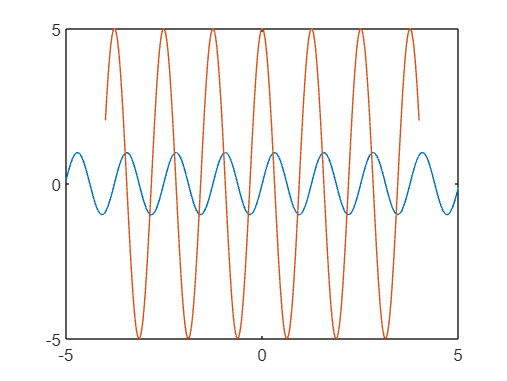

%Plot the graph of y and y_x in interval [-4,4]
fplot(y)
hold on
fplot(y_x,[-4,4])
hold off

%Find the second order of f=e^x*cos(x) at x=2 and store it is output at f_2
f=exp(x)*cos(x);
f_2=diff(f,x,2)

$$f\_2 = -2\,{\mathrm{e}}^{x}\,\sin\left(x\right)$$

subs(f_2,x,2)

$$ans = -2\,{\mathrm{e}}^{2}\,\sin\left(2\right)$$

%Find the derivative of one function sin(x^2).Find the value of derivative at x=2
P=sin(x^2)

$$P = \sin\left(x^{2}\right)$$

subs(P,x,2)

$$ans = \sin\left(4\right)$$